# BME3053C Final Project

BME 3053C Homework 10 MATLAB Header and Live Script

Authors: Christian Nguyen, Kaitlyn McCarty, Benjamin Tondre

Course: BME 3053C Computer Applications for BME

Term: Fall 2023

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: christian.nguyen@ufl.edu

November 10th, 2023

**Step to Be Conducted before Running Program:**

**1) Download the Breast Histopathology Images Archive from Paul Mooney at **[**https://www.kaggle.com/datasets/paultimothymooney/breast-histopathology-images**](https://www.kaggle.com/datasets/paultimothymooney/breast-histopathology-images)

**2) Modify the GoogLeNet CNN architecture found in MATLAB's Deep Network Designer App **

**    A) Install the GoogLeNet CNN architecture**

**    B) Zoom into the Bottom of the Network and Delete the                         3rd last layer (fullyConnectedLayer)**

**    C) Add a fullyConnectedLayer and change the OutputSize to 2**

**    D) Connect the fullyConnected Layer in the 3rd last layer position**

**    E) Delete the last layer (classificationLayer)**

**    F) Add a classificationLayer in the last layer position**

**   G) Export the Network Architecture to the Workspace **

**   H) Save the Modified Network as original_network.mat and make sure that it is in the M drive**

**Step 1: Load the Breast Histopathology Image Archive into MATLAB**

imds=imageDatastore("C:\final project matlab\archive\","IncludeSubfolders",true,"LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\archive\10253\0\10253_idx5_x1001_y1001_class0.png';
                              ' ...\archive\10253\0\10253_idx5_x1001_y1051_class0.png';
                              ' ...\archive\10253\0\10253_idx5_x1001_y1101_class0.png'
                               ... and 555045 more
                              }
                     Folders: {
                              'C:\final project matlab\archive'
                              }
                      Labels: [0; 0; 0 ... and 555045 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


**Step 2: Review the Data Set Labels**

imds_labels=imds.Labels

imds_labels = 555048×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


**Step 3: Split the Data Set into Train Sets and Test Sets with 100,000 Images with 50,000 IDC+ and 50,000 IDC- Images in the Train Set**

[imds_train,imds_test]=splitEachLabel(imds,50000)

imds_train =   ImageDatastore with properties:

                       Files: {
                              ' ...\archive\10253\0\10253_idx5_x1001_y1001_class0.png';
                              ' ...\archive\10253\0\10253_idx5_x1001_y1051_class0.png';
                              ' ...\archive\10253\0\10253_idx5_x1001_y1101_class0.png'
                               ... and 97 more
                              }
                     Folders: {
                              'C:\final project matlab\archive'
                              }
                      Labels: [0; 0; 0 ... and 97 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


imds_test =   ImageDatastore with properties:

                       Files: {
                              ' ...\archive\10253\0\10253_idx5_x1101_y1251_class0.png';
                              ' ...\archive\10253\0\10253_idx5_x1101_y1751_class0.png';
                              ' ...\archive\10253\0\10253_idx5_x1101_y1801_class0.png'
                               ... and 554945 more
                              }
                     Folders: {
                              'C:\final project matlab\archive'
                              }
                      Labels: [0; 0; 0 ... and 554945 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


**Step 4: Process the Train and Test Sets to meet the CNN Network Specifications **

aug_imds_train=augmentedImageDatastore([224,224],imds_train)

aug_imds_train =   augmentedImageDatastore with properties:

             NumObservations: 100
                       Files: {100×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


aug_imds_test=augmentedImageDatastore([224,224],imds_test)

aug_imds_test =   augmentedImageDatastore with properties:

             NumObservations: 554948
                       Files: {554948×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


**Step 5: Load the untrained CNN**

load("original_network.mat")

**Step 6: Specify the training options using the settings "sgdm","InitialLearnRate",0.001,MaxEpoch=2,VerboseFrequency=20, Plots="training-progress"**

opts=trainingOptions("sgdm","InitialLearnRate",0.001,MaxEpoch=30,VerboseFrequency=20,Plots="training-progress")

opts =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 1
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 20
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
       

**Step 7: Train the CNN with the Train Set and save the trained CNN as a variable named trained_CNN and the specified options and save the information as a variable named info**

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:09 |       47.66% |       1.3196 |          0.0010 |
|       1 |          20 |       00:00:23 |       78.91% |       0.4594 |          0.0010 |
|       1 |          40 |       00:00:37 |       88.28% |       0.3597 |          0.0010 |
|       1 |          60 |       00:00:51 |       85.16% |       0.2865 |          0.0010 |
|       1 |          80 |       00:01:03 |       87.50% |       0.2846 |          0.0010 |
|       1 |         100 |       00:01:14 |       81.25% |       0.4032 |          0.0010 |
|       1 |         120 |  

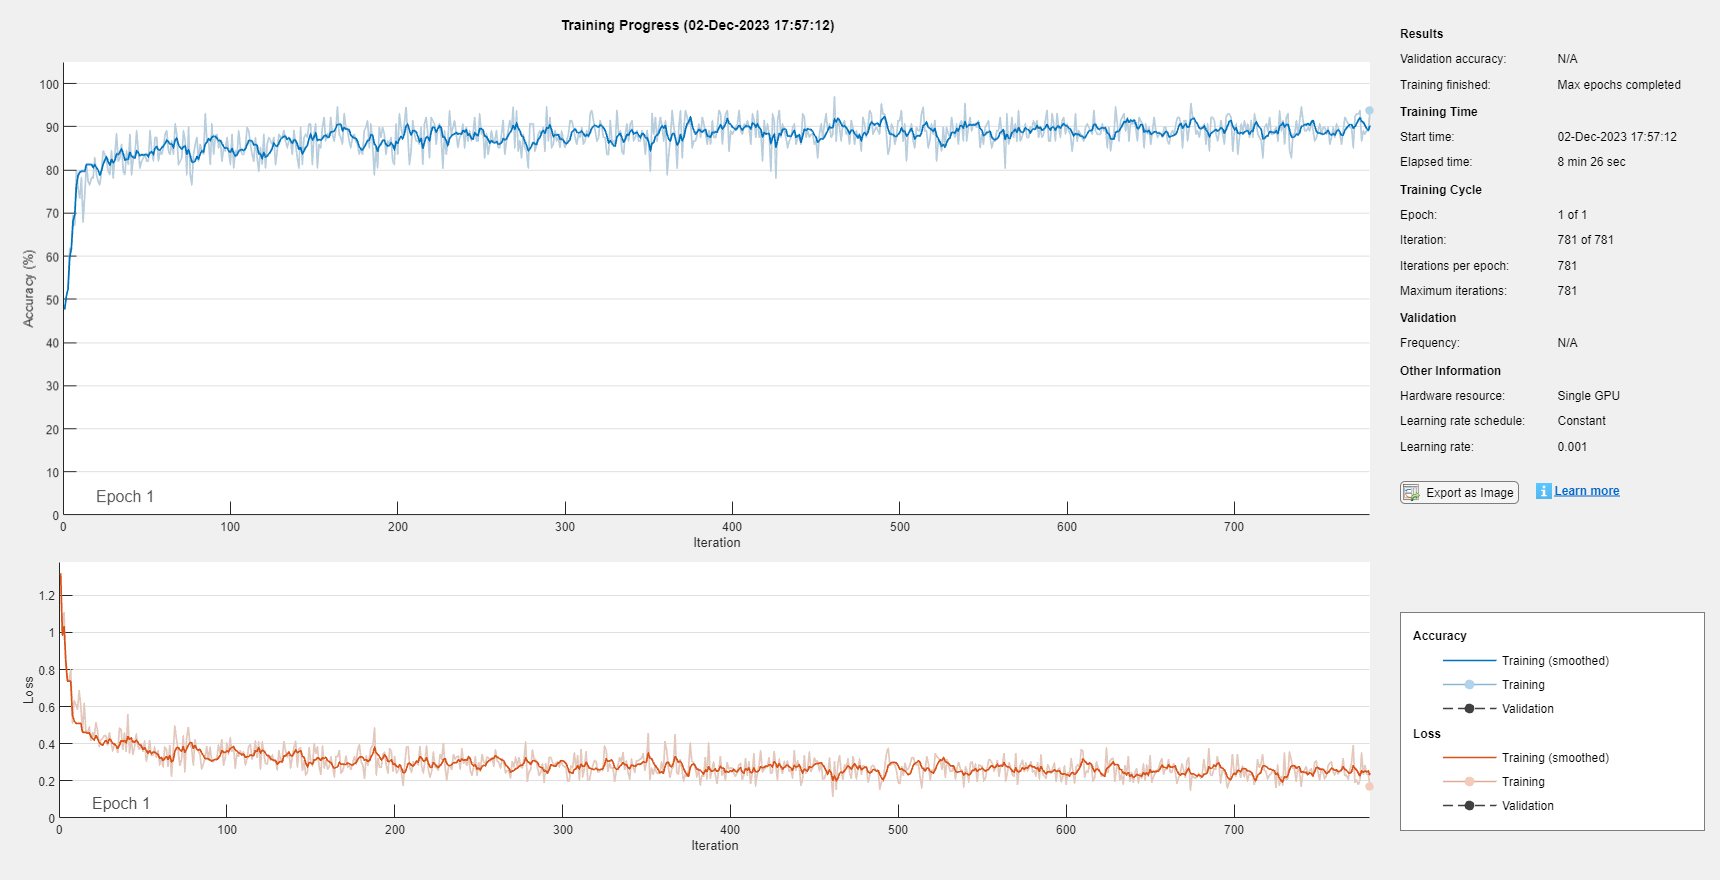

trained_CNN =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


info = struct with fields:
              TrainingLoss: [1.3196 0.9853 1.1081 0.8264 0.7382 0.7425 0.7986 0.5101 0.6321 0.6145 0.5843 0.6848 0.6045 0.4619 0.6184 0.4708 0.4551 0.4906 0.4196 0.4594 0.4382 0.5138 0.4687 0.3843 0.4213 0.4291 0.4457 0.4419 0.3917 0.4602 0.4086 … ]
          TrainingAccuracy: [47.6562 50.7812 52.3438 61.7188 61.7188 69.5312 67.1875 79.6875 75.7812 73.4375 78.1250 67.9688 74.2188 81.2500 77.3438 76.5625 78.1250 78.1250 82.8125 78.9062 77.3438 76.5625 79.6875 84.3750 83.5938 82.0312 79.6875 … ]
             BaseLearnRate: [0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 … ]
    OutputNetworkIteration: 781


[trained_CNN,info]=trainNetwork(aug_imds_train,original_network,opts)

**Step 8: Verify the CNN using the Test Set**

im_prediction=classify(trained_CNN,aug_imds_test)

im_prediction = 131962×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


**Step 9: Create a set of verified identifiers of the Test Set**

im_real=imds_test.Labels

im_real = 131962×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


**Step 10: Determine the amount of correctly identified images**

numCorrect=nnz(im_prediction==im_real)

numCorrect = 90856

**Step 11: Determine the fraction of correctly identified images **

fractCorrect=numCorrect/numel(im_real)

fractCorrect = 0.6885

**Step 12: Create a Confusion Matrix with the determined data**

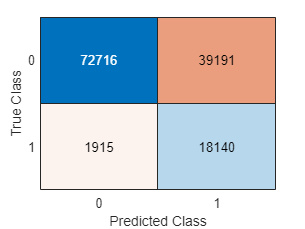

confusion_matrix =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties


confusion_matrix=confusionchart(im_real,im_prediction)